# Solution to Example 19.5 Low Pass Filter

This example represents the low-pass filter used in the signal generator project for **EG-152: Analogue Design**.

a) A triangle waveform 𝑥(𝑡) with frequency $\Omega_0 =2\mathrm{𝜋}/\mathrm{𝑇}$ is shown in Fig. 19.5. 

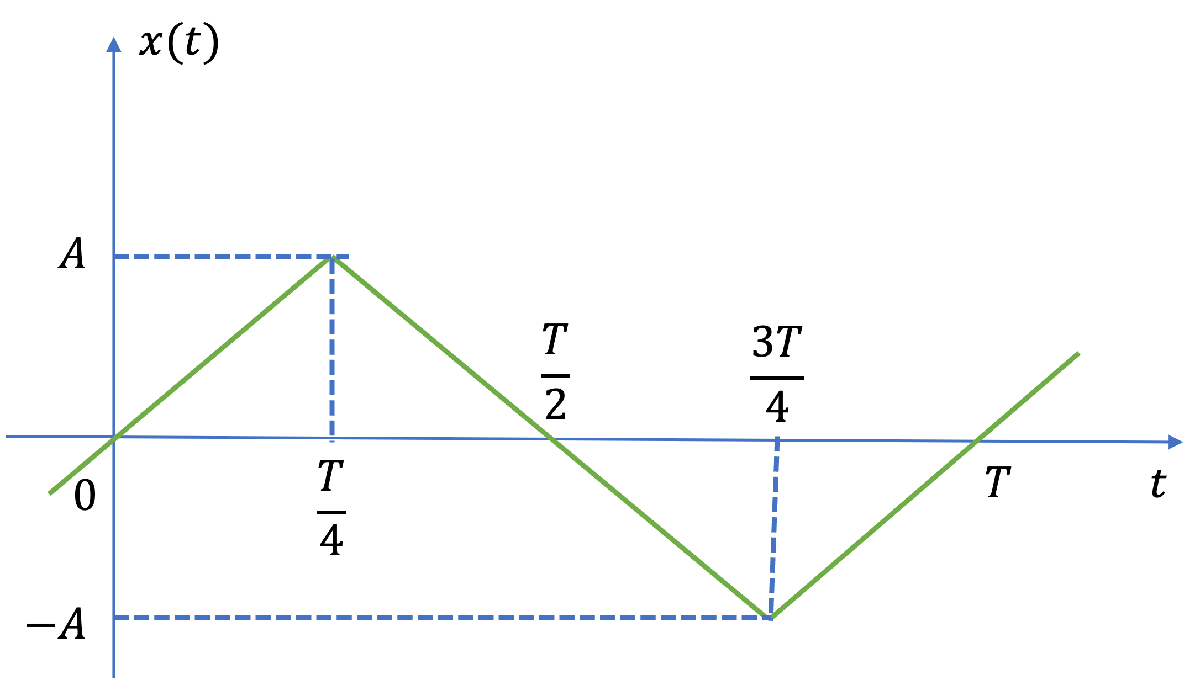

Fig. 19.5 A Triangle Waveform

Determine the exponential Fourier series coefficients 𝐶𝑘 for this waveform and use this result to show that the trigonomentric Fourier series for this triangle waveform is 

## Solution

syms A theta T k t
assume(k,'integer')
u0(t) = heaviside(t);

Define the equations for the lines - we will integrate these later

l1(t) = (4*A/T)*t

$$l1(t) = \frac{4\,A\,t}{T}$$

l2(t) = -(4*A/T)*t + 2*A

$$l2(t) = 2\,A-\frac{4\,A\,t}{T}$$

l3(t) = (4*A/T)*t - 4*A

$$l3(t) = \frac{4\,A\,t}{T}-4\,A$$

Plot to check

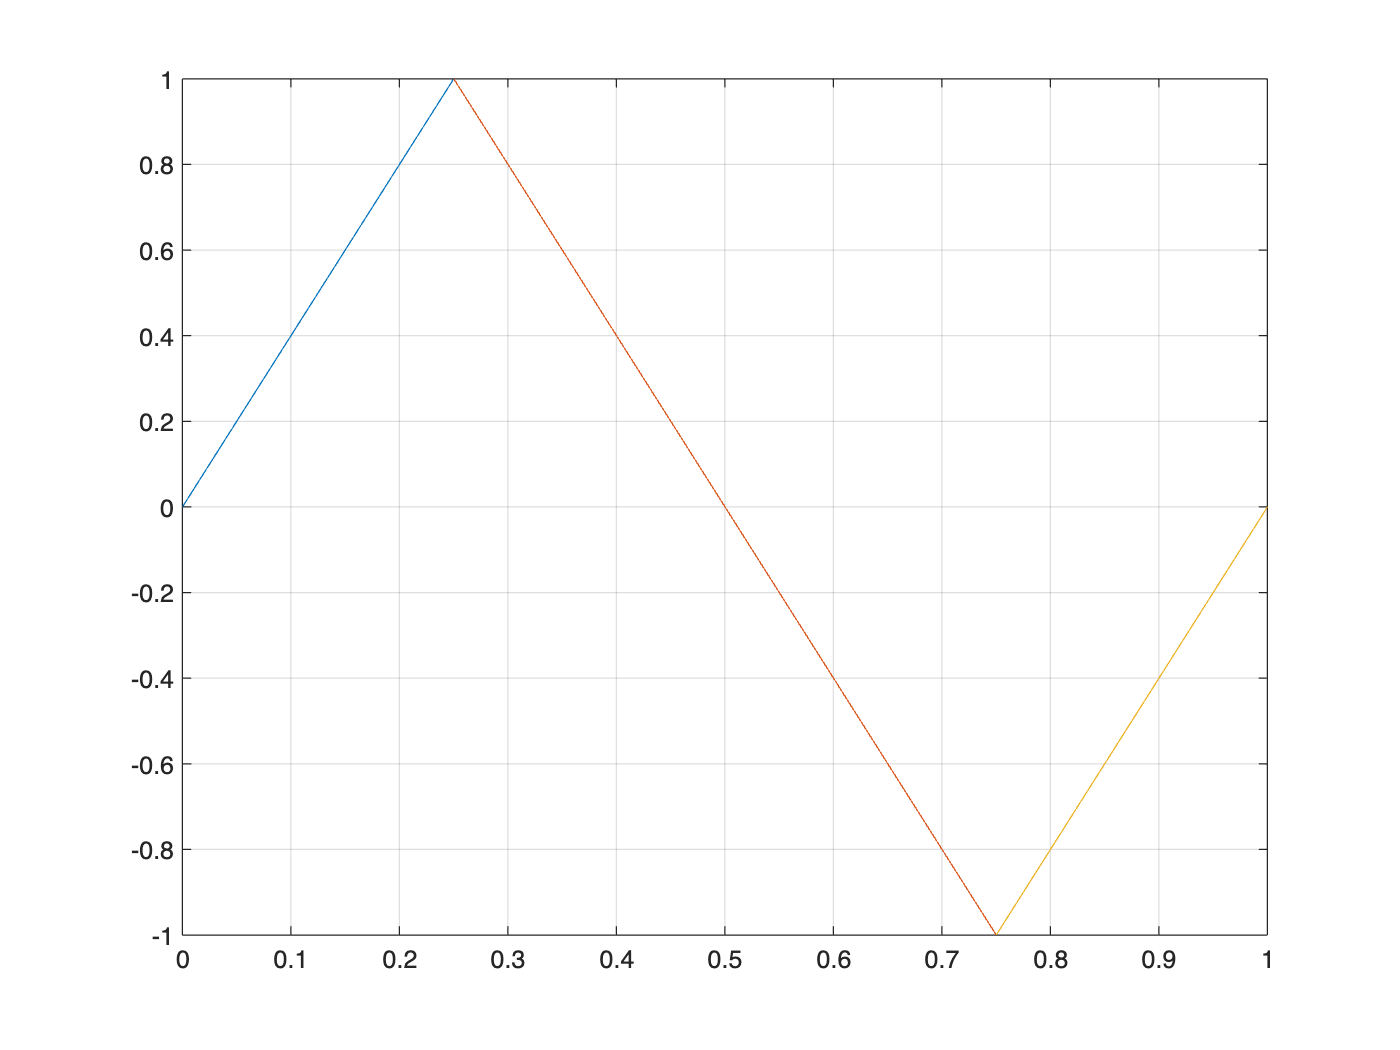

fplot(subs(l1(t),[A,T],[1,1]),[0,1/4]),grid
hold on
fplot(subs(l2(t),[A,T],[1,1]),[1/4,3/4])
fplot(subs(l3(t),[A,T],[1,1]),[3/4,1])
hold off

### Compute Fourier Series Coefficients

We will use the function `FourierSeries`

We will use $u_0(t)$ as a "gating function" so we have a single expression that can be integrated. $T_0$ will be $1/(2\pi)$

f(theta) = l1(t)*(u0(t)-u0(t-T_0/4))+...
    l2(t)*(u0(t-T_0/4)-u0(t-3*T_0)/4)+...
    l3(t)*(u0(t-3*T_0/4)-u0(t-T_0))

$$f(theta) = \left(\mathrm{heaviside}\left(t-2\,\pi \right)-\mathrm{heaviside}\left(t-\frac{3\,\pi }{2}\right)\right)\,\left(4\,A-\frac{4\,A\,t}{T}\right)+\left(\mathrm{heaviside}\left(t-\frac{\pi }{2}\right)-\frac{\mathrm{heaviside}\left(t-6\,\pi \right)}{4}\right)\,\left(2\,A-\frac{4\,A\,t}{T}\right)+\frac{4\,A\,t\,\left(\mathrm{heaviside}\left(t\right)-\mathrm{heaviside}\left(t-\frac{\pi }{2}\right)\right)}{T}$$

fplot(subs(f(theta),A,1),[0,T_0]),grid

Error using fplot>singleFplot
Input must be a function or functions of a single variable.

Error in fplot>@(f)singleFplot(cax,{f},limits,extraOpts,args) (line 200)
        hObj = cellfun(@(f) singleFplot(cax,{f},limits,extraOpts,args),fn{1},'UniformOutput',false);

Error in fplot>vectorizeFplot (

[Ck,w] = FourierSeries(f(t),T_0,[1:13])
Ck(2)

i2 = int(l2(theta)*exp(-j*k*theta),-pi/4,pi/4)
i2 = int(l2(theta)*exp(-j*k*theta),-pi/4,pi/4)
f(t) = l1(t)*(u0(theta) - u0(theta-pi/4)) + l2(t)*(u0(theta-pi/4)-u0(theta-3*pi/4))

Compute the limits

l11 = subs(i1,theta,-sym(pi)/4)
l12 = subs(i1,theta,sym(pi)/4)
l21 = subs(i2,theta,sym(pi)/4)
l22 = subs(i2,theta,3*sym(pi)/4)

Now compute $C_k$

C_k = 1/(2*sym(pi))*(l11 - l12 + l21 - l22)
C_k = expand(C_k)

C_1 = simplify(subs(C_k,k,1))
C_2 = subs(C_k,k,2)
C_3 = subs(C_k,k,3)
C_4 = subs(C_k,k,4)